### Create uncertain linear state space model

s = tf('s');

Ts_c = 1/200;

J_xx = ureal('J_xx', 0.001630, 'Percentage', 3);
J_yy = ureal('J_yy', 0.002156, 'Percentage', 4);
J_zz = ureal('J_zz', 0.003281, 'Percentage', 3);

A = [0 0 0 1 0 0;
     0 0 0 0 1 0;
     0 0 0 0 0 1;
     0 0 0 0 0 0;
     0 0 0 0 0 0;
     0 0 0 0 0 0];

B = [0 0 0;
     0 0 0;
     0 0 0;
     1/J_xx 0 0;
     0 1/J_yy 0;
     0 0 1/J_zz];

C = [1 0 0 0 0 0;
     0 1 0 0 0 0;
     0 0 1 0 0 0];

D = [0 0 0;
     0 0 0;
     0 0 0];

Q = ss(A, B, C, D);
Q.StateName = {'theta_x', 'theta_y', 'theta_z', 'omega_x', 'omega_y', 'omega_z'};
Q.InputName = 'M_d';
Q.OutputName = 'bar_theta';

tf(Q(1,1))


ans =
 
  From input "M_d(1)" to output "bar_theta(1)":
  613.5
  -----
   s^2
 
Continuous-time transfer function.



% Define uncertain transfer functions for actuator dynamics
F_tc = ureal('F_tc', 0.033, 'Percentage', 18);
F_k = ureal('F_k', 1, 'Percentage', 5);
F_td = ureal('F_td', 0.0349, 'Percentage', 26);

F_i = F_k/(F_tc*s + 1);%exp(-F_td*s)*F_k/(F_tc*s + 1);

F = [F_i  0       0; 
     0              F_i   0;
     0              0               F_i];
F.u = 'u';
F.y = 'M';

d_add = sumblk('M_d = d + M',3);

% Connect all above blocks
P = connect(F, d_add, Q, {'u', 'd'}, {'bar_theta'})*exp(-usample(F_td,20)*s)

20x1 array of uncertain continuous-time state-space models.
Each model has 3 outputs, 6 inputs, 15 states, and the following uncertain blocks:
  F_k: Uncertain real, nominal = 1, variability = [-5,5]%, 3 occurrences
  F_tc: Uncertain real, nominal = 0.033, variability = [-18,18]%, 3 occurrences
  J_xx: Uncertain real, nominal = 0.00163, variability = [-3,3]%, 1 occurrences
  J_yy: Uncertain real, nominal = 0.00216, variability = [-4,4]%, 1 occurrences
  J_zz: Uncertain real, nominal = 0.00328, variability = [-3,3]%, 1 occurrences


tf(P.nominal(:,:,1,1))


ans =
 
  From input "u(1)" to output...
                                      1.859e04
   bar_theta(1):  exp(-0.0305*s) * --------------
                                   s^3 + 30.3 s^2
 
   bar_theta(2):  0
 
   bar_theta(3):  0
 
  From input "u(2)" to output...
   bar_theta(1):  0
 
                                      1.406e04
   bar_theta(2):  exp(-0.0305*s) * --------------
                                   s^3 + 30.3 s^2
 
   bar_theta(3):  0
 
  From input "u(3)" to output...
   bar_theta(1):  0
 
   bar_theta(2):  0
 
                                        9236
   bar_theta(3):  exp(-0.0305*s) * --------------
                                   s^3 + 30.3 s^2
 
  From input "d(1)" to output...
                                   613.5
   bar_theta(1):  exp(-0.0305*s) * -----
                                    s^2
 
   bar_theta(2):  0
 
   bar_theta(3):  0
 
  From input "d(2)" to output...
   bar_theta(1):  0
 
                                   463.8
   bar_theta(2):  


figureWidth = 10; % cm (max. 15)
figureRatio = 0.6; % height to width ratio
set(groot, 'defaultTextInterpreter', 'latex')
set(groot, 'defaultAxesTickLabelInterpreter', 'latex');
set(groot, 'defaultLegendInterpreter', 'latex');

## PID Control design

Simulate = false;

Roll and pitch specs

Ts = 1; % 1 s
OS = 15; % 15 %


Roll controller design

lead = 87.5; % deg 87.5
K = 0.0012; % 0.0012
T_i = 2; % 2

zeta = -log(OS/100)/sqrt( pi^2+log(OS/100)^2 );
wn = 4/zeta/Ts;
wp = wn*sqrt(1-2*zeta^2);

Ma = 1/( 2*zeta*sqrt(1-zeta^2) ); %overbound
Mb = .98; %underbound
% Md1 = abs(freqresp(P.NominalValue(1,1,1,1),wp_d))/abs(freqresp(A,wp_d));
% Md2 = abs(freqresp(P.NominalValue(1,1,1,1),wp_d/10))/abs(freqresp(A,wp_d/10));

w_max = wp;
phi_max = lead*pi/180;
alpha = w_max/tan( (phi_max+pi/2)/2 )

alpha = 0.1152

beta = w_max^2/alpha

beta = 241.9699

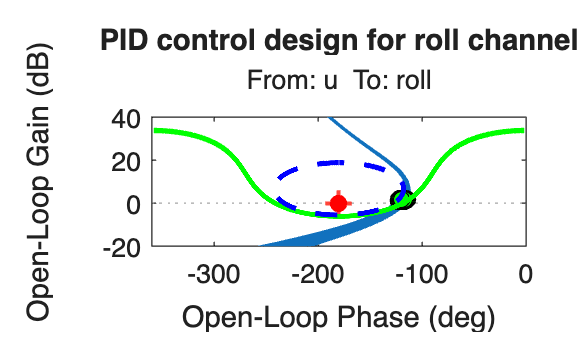


G_PID_roll = (K*(1 + s/alpha)*(1 + T_i*s))/(s*T_i*(1 + s/beta));
G_PID_roll.InputName = {'e(1)'};
G_PID_roll.OutputName = {'u(1)'};

% bodemag(G_PID_roll)

L_PID_roll = connect(G_PID_roll, P(1,1), {'e(1)'}, {'bar_theta(1)'});
L_PID_roll.InputName = 'u';
L_PID_roll.OutputName = 'roll';

% bodemag(L_PID_roll)

figure,clf,hold on

M = [1/Ma 1/Mb];
for k = 1:length(M)
    phi = linspace(0,2*pi,1e4);
    c = -1;
    r = M(k);
    H = c + r*exp(1i*phi);

    mag_H = 20*log10( abs(H) );
    phi_H = angle( H )*180/pi;
    for i=1:length(phi_H)
        if( phi_H(i) > 0), phi_H(i) = phi_H(i)-360; end
    end

    if( k==1 )
        plot( phi_H(2:end-1),-mag_H(2:end-1),'--b',LineWidth=2,DisplayName='Ma' )
    elseif( k==2 )
        plot( phi_H(2:end-1),-mag_H(2:end-1),'-g',LineWidth=2,DisplayName='Mb' )
    % elseif( k==3 )
    %     plot( phi_H(2:end-1),mag_H(2:end-1),'-r',LineWidth=2,DisplayName='Md1' )
    % else
    %     plot( phi_H(2:end-1),mag_H(2:end-1),'--k',LineWidth=2,DisplayName='Md2' )
    end
end

for i = 1:20
    sys_i = usample(L_PID_roll);
    Lw = squeeze( freqresp(sys_i,wp) );
    ang_Lw = angle(Lw)*180/pi;
    if( ang_Lw > 0 )
        ang_Lw = ang_Lw-360;
    end
    plot(ang_Lw,20*log10(abs(Lw)),'o','MarkerFaceColor','g','MarkerEdgeColor','k')
end

nichols(L_PID_roll,{0.01,500})

plot(-180,0,'ro',MarkerFaceColor='r',DisplayName='CriticalPoint')

xlim([-360,0]),ylim([-20 40])
title('PID control design for roll channel')



% for i = 1:20
%     sys_i = usample(L_PID_roll);
%     Lw = squeeze( freqresp(sys_i,wp_d) );
%     ang_Lw = angle(Lw)*180/pi;
%     if( ang_Lw > 0 )
%         ang_Lw = ang_Lw-360;
%     end
%     plot(ang_Lw,20*log10(abs(Lw)),'o','MarkerFaceColor','r','MarkerEdgeColor','k')
% end
% 
% for i = 1:20
%     sys_i = usample(L_PID_roll);
%     Lw = squeeze( freqresp(sys_i,wp_d/10) );
%     ang_Lw = angle(Lw)*180/pi;
%     if( ang_Lw > 0 )
%         ang_Lw = ang_Lw-360;
%     end
%     plot(ang_Lw,20*log10(abs(Lw)),'o','MarkerFaceColor','k','MarkerEdgeColor','k')
% end

set(findall(gcf, '-property', 'FontSize'), 'FontSize', 12);
set(gcf,'Units','centimeters','Position',[3 3 figureWidth figureRatio*figureWidth])
set(gcf,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[figureWidth figureRatio*figureWidth])

hold off


G_PID_roll_DT = c2d(G_PID_roll,Ts_c)


G_PID_roll_DT =
 
  From input "e(1)" to output "u(1)":
  2.52 z^2 - 5.036 z + 2.516
  --------------------------
    z^2 - 1.298 z + 0.2982
 
Sample time: 0.005 seconds
Discrete-time transfer function.



% bode(L_PID_roll)
% opts = robOptions('Display', 'on', 'Sensitivity', 'on');
% [margin, wcu, info] = robstab(feedback(L_PID_roll, 1), opts);

Pitch controller design

lead = 87.5; % deg
K = 0.0015;
T_i = 1.8;

zeta = -log(OS/100)/sqrt( pi^2+log(OS/100)^2 );
wn = 4/zeta/Ts;
wp = wn*sqrt(1-2*zeta^2);

Ma = 1/( 2*zeta*sqrt(1-zeta^2) ); %overbound
Mb = .98; %underbound

w_max = wp;
phi_max = lead*pi/180;
alpha = w_max/tan( (phi_max+pi/2)/2 )

alpha = 0.1152

beta = w_max^2/alpha

beta = 241.9699


G_PID_pitch = (K*(1 + s/alpha)*(1 + T_i*s))/(s*T_i*(1 + s/beta))


G_PID_pitch =
 
  0.6533 s^2 + 0.4382 s + 0.04181
  -------------------------------
       0.2074 s^2 + 50.18 s
 
Continuous-time transfer function.


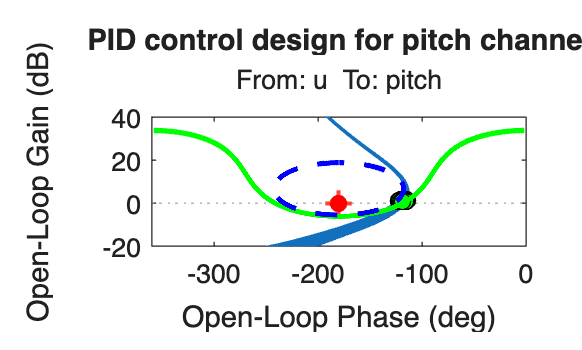

G_PID_pitch.InputName = {'e(2)'};
G_PID_pitch.OutputName = {'u(2)'};

% bodemag(G_PID_pitch)

L_PID_pitch = connect(G_PID_pitch, P(2,2), {'e(2)'}, {'bar_theta(2)'});
L_PID_pitch.InputName = 'u';
L_PID_pitch.OutputName = 'pitch';

% bodemag(L_PID_pitch)

figure(1),clf,hold on

M = [Ma Mb];
for k = 1:length(M)
    phi = linspace(0,2*pi,1e4);
    c = -1;
    r = 1/M(k);
    H = c + r*exp(1i*phi);

    mag_H = 20*log10( abs(H) );
    phi_H = angle( H )*180/pi;
    for i=1:length(phi_H)
        if( phi_H(i) > 0), phi_H(i) = phi_H(i)-360; end
    end

    if( k==1 )
        plot( phi_H(2:end-1),-mag_H(2:end-1),'--b',LineWidth=2 )
    else
        plot( phi_H(2:end-1),-mag_H(2:end-1),'-g',LineWidth=2 )
    end
end
for i = 1:20
    sys_i = usample(L_PID_pitch);
    Lw = squeeze( freqresp(sys_i,wp) );
    ang_Lw = angle(Lw)*180/pi;
    if( ang_Lw > 0 )
        ang_Lw = ang_Lw-360;
    end
    plot(ang_Lw,20*log10(abs(Lw)),'o',MarkerFaceColor='g',MarkerEdgeColor='k')
end
nichols(L_PID_pitch,{0.01,500}),plot(-180,0,'ro',MarkerFaceColor='r')
xlim([-360,0]),ylim([-20 40])
title('PID control design for pitch channel')
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 12);
set(gcf,'Units','centimeters','Position',[3 3 figureWidth figureRatio*figureWidth])
set(gcf,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[figureWidth figureRatio*figureWidth])
hold off


G_PID_pitch_DT = c2d(G_PID_pitch,Ts_c)


G_PID_pitch_DT =
 
  From input "e(2)" to output "u(2)":
  3.15 z^2 - 6.295 z + 3.144
  --------------------------
    z^2 - 1.298 z + 0.2982
 
Sample time: 0.005 seconds
Discrete-time transfer function.



% bode(L_PID_pitch)
% opts = robOptions('Display', 'on', 'Sensitivity', 'on');
% [margin, wcu, info] = robstab(feedback(L_PID_pitch, 1), opts);


Yaw specs

Ts = 3; % s
OS = 15; % %

Yaw controller design

lead = 78; % deg
K = 0.0022;
T_i = 5;

zeta = -log(OS/100)/sqrt( pi^2+log(OS/100)^2 );
wn = 4/zeta/Ts;
wp = wn*sqrt(1-2*zeta^2);

Ma = 1/( 2*zeta*sqrt(1-zeta^2) ); %overbound
Mb = .98; %underbound

w_max = wp;
phi_max = lead*pi/180;
alpha = w_max/tan( (phi_max+pi/2)/2 )

alpha = 0.1850

beta = w_max^2/alpha

beta = 16.7447


G_PID_yaw = (K*(1 + s/alpha)*(1 + T_i*s))/(s*T_i*(1 + s/beta))


G_PID_yaw =
 
  0.1842 s^2 + 0.07091 s + 0.006814
  ---------------------------------
        0.9249 s^2 + 15.49 s
 
Continuous-time transfer function.


G_PID_yaw.InputName = {'e(3)'};
G_PID_yaw.OutputName = {'u(3)'};

% bodemag(G_PID_yaw)

L_PID_yaw = connect(G_PID_yaw, P(3,3), {'e(3)'}, {'bar_theta(3)'})

20x1 array of uncertain continuous-time state-space models.
Each model has 1 outputs, 1 inputs, 7 states, and the following uncertain blocks:
  F_k: Uncertain real, nominal = 1, variability = [-5,5]%, 1 occurrences
  F_tc: Uncertain real, nominal = 0.033, variability = [-18,18]%, 1 occurrences
  J_zz: Uncertain real, nominal = 0.00328, variability = [-3,3]%, 1 occurrences


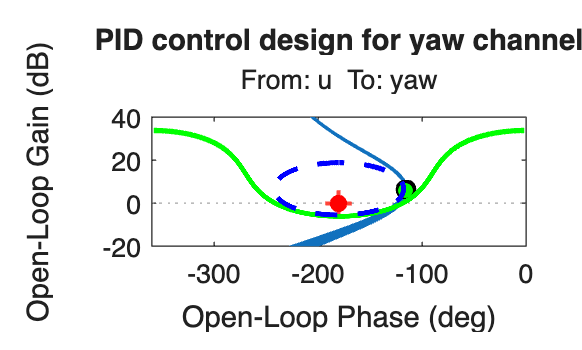

L_PID_yaw.InputName = 'u';
L_PID_yaw.OutputName = 'yaw';

% bodemag(L_PID_yaw)

figure(1),clf,hold on

M = [Ma Mb];
for k = 1:length(M)
    phi = linspace(0,2*pi,1e4);
    c = -1;
    r = 1/M(k);
    H = c + r*exp(1i*phi);

    mag_H = 20*log10( abs(H) );
    phi_H = angle( H )*180/pi;
    for i=1:length(phi_H)
        if( phi_H(i) > 0), phi_H(i) = phi_H(i)-360; end
    end

    if( k==1 )
        plot( phi_H(2:end-1),-mag_H(2:end-1),'--b',LineWidth=2 )
    else
        plot( phi_H(2:end-1),-mag_H(2:end-1),'-g',LineWidth=2 )
    end
end
for i = 1:20
    sys_i = usample(L_PID_yaw);
    Lw = squeeze( freqresp(sys_i,wp) );
    ang_Lw = angle(Lw)*180/pi;
    if( ang_Lw > 0 )
        ang_Lw = ang_Lw-360;
    end
    plot(ang_Lw,20*log10(abs(Lw)),'o',MarkerFaceColor='g',MarkerEdgeColor='k')
end
nichols(L_PID_yaw,{0.01,500}),plot(-180,0,'ro',MarkerFaceColor='r')
xlim([-360,0]),ylim([-20 40])
title('PID control design for yaw channel')
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 12);
set(gcf,'Units','centimeters','Position',[3 3 figureWidth figureRatio*figureWidth])
set(gcf,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[figureWidth figureRatio*figureWidth])
hold off


G_PID_yaw_DT = c2d(G_PID_yaw,Ts_c)


G_PID_yaw_DT =
 
  From input "e(3)" to output "u(3)":
  0.1992 z^2 - 0.3979 z + 0.1988
  ------------------------------
      z^2 - 1.92 z + 0.9197
 
Sample time: 0.005 seconds
Discrete-time transfer function.



% bode(L_PID_yaw)
% opts = robOptions('Display', 'on', 'Sensitivity', 'on');
% [margin, wcu, info] = robstab(feedback(L_PID_yaw, 1), opts);


Simulate controller

AttController = "PID";
initVars;
if Simulate
    outPID = sim("Simulation/QuadSimControl.slx");
    figure, clf, hold on
    plot(outPID.att.time, outPID.att.signals.values(:,1))
    plot(outPID.att.time, outPID.att.signals.values(:,2))
    plot(outPID.att.time, outPID.att.signals.values(:,3))
    legend('yaw','pitch','roll')
    hold off
    figure, clf, hold on
    plot(outPID.pos.time, outPID.pos.signals.values(:,1))
    plot(outPID.pos.time, outPID.pos.signals.values(:,2))
    plot(outPID.pos.time, outPID.pos.signals.values(:,3))
    legend('x','y','z')
    hold off
end

exp(-F_td.NominalValue*s)*(F_k.NominalValue/(F_tc.NominalValue*s + 1))


ans =
 
                        1
  exp(-0.0349*s) * -----------
                   0.033 s + 1
 
Continuous-time transfer function.


## PD+ESO control design

Simulate = false;

ESO design

w_o_PDESO = 7; % rad/s
b_0_roll_PDESO = 1/J_xx_u.NominalValue;
b_0_pitch_PDESO = 1/J_yy_u.NominalValue;
b_0_yaw_PDESO = 1/J_zz_u.NominalValue;

ONE = ones(1,1,'like',b_0_roll_PDESO);

A_eso_CT =  [0 0 0 1 0 0 0 0 0;
             0 0 0 0 1 0 0 0 0;
             0 0 0 0 0 1 0 0 0;
             0 0 0 0 0 0 1 0 0;
             0 0 0 0 0 0 0 1 0;
             0 0 0 0 0 0 0 0 1;
             0 0 0 0 0 0 0 0 0;
             0 0 0 0 0 0 0 0 0;
             0 0 0 0 0 0 0 0 0]*ONE;
B_eso_CT =  [0 0 0;
             0 0 0;
             0 0 0;
             b_0_roll_PDESO 0 0;
             0 b_0_pitch_PDESO 0;
             0 0 b_0_yaw_PDESO;
             0 0 0;
             0 0 0;
             0 0 0;]*ONE;

C_eso_CT =  [1 0 0 0 0 0 0 0 0;
             0 1 0 0 0 0 0 0 0;
             0 0 1 0 0 0 0 0 0]*ONE;

L_CT =   [3*w_o_PDESO   0           0;
            0       3*w_o_PDESO^2     0;
            0       0           w_o_PDESO^3;
            3*w_o_PDESO   0           0;
            0       3*w_o_PDESO^2     0;
            0       0           w_o_PDESO^3;
            3*w_o_PDESO   0           0;
            0       3*w_o_PDESO^2     0;
            0       0           w_o_PDESO^3;]*ONE;

ESO_CT = ss(A_eso_CT,B_eso_CT,C_eso_CT, zeros(3,3));

PDESO_ESO_DT = c2d(ESO_CT, Ts_c);

vec_wo = 1:0.01:1+0.01*(6+3-1);
obs_poles = -w_o_PDESO*vec_wo;
obs_poles = exp(obs_poles*Ts_c);

L_PDESO_DT = place(PDESO_ESO_DT.A',PDESO_ESO_DT.A'*PDESO_ESO_DT.C',obs_poles)';

Roll and pitch specs

Ts = 1; % s
OS = 15; % %

Roll controller design

lead = 80; % deg
K = 0.0044;

zeta = -log(OS/100)/sqrt( pi^2+log(OS/100)^2 );
wn = 4/zeta/Ts;
wp = wn*sqrt(1-2*zeta^2);

Ma = 1/( 2*zeta*sqrt(1-zeta^2) ); %overbound
Mb = .98; %underbound

w_max = wp;
phi_max = lead*pi/180;
alpha = w_max/tan( (phi_max+pi/2)/2 )

alpha = 0.4619

beta = w_max^2/alpha

beta = 60.3484


G_PD_roll = (K*(1 + s/alpha))/(1 + s/beta)


G_PD_roll =
 
  0.2655 s + 0.1227
  -----------------
  0.4619 s + 27.88
 
Continuous-time transfer function.


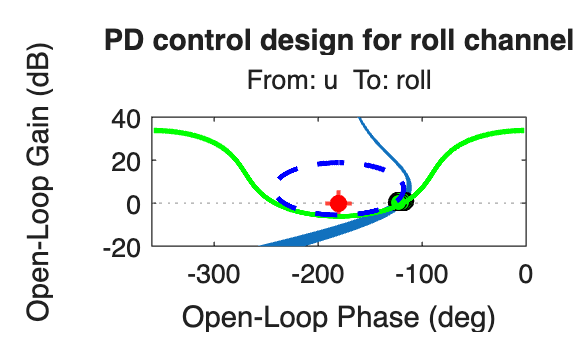

G_PD_roll.InputName = {'e(1)'};
G_PD_roll.OutputName = {'u(1)'};

% bodemag(G_PD_roll)

L_PD_roll = connect(G_PD_roll, P(1,1), {'e(1)'}, {'bar_theta(1)'});
L_PD_roll.InputName = 'u';
L_PD_roll.OutputName = 'roll';

% bodemag(L_PD_roll)

figure(1),clf,hold on

M = [Ma Mb];
for k = 1:length(M)
    phi = linspace(0,2*pi,1e4);
    c = -1;
    r = 1/M(k);
    H = c + r*exp(1i*phi);

    mag_H = 20*log10( abs(H) );
    phi_H = angle( H )*180/pi;
    for i=1:length(phi_H)
        if( phi_H(i) > 0), phi_H(i) = phi_H(i)-360; end
    end

    if( k==1 )
        plot( phi_H(2:end-1),-mag_H(2:end-1),'--b',LineWidth=2 )
    else
        plot( phi_H(2:end-1),-mag_H(2:end-1),'-g',LineWidth=2 )
    end
end
for i = 1:20
    sys_i = usample(L_PD_roll);
    Lw = squeeze( freqresp(sys_i,wp) );
    ang_Lw = angle(Lw)*180/pi;
    if( ang_Lw > 0 )
        ang_Lw = ang_Lw-360;
    end
    plot(ang_Lw,20*log10(abs(Lw)),'o',MarkerFaceColor='g',MarkerEdgeColor='k')
end
nichols(L_PD_roll,{0.01,500}),plot(-180,0,'ro',MarkerFaceColor='r')
xlim([-360,0]),ylim([-20 40])
title('PD control design for roll channel')
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 12);
set(gcf,'Units','centimeters','Position',[3 3 figureWidth figureRatio*figureWidth])
set(gcf,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[figureWidth figureRatio*figureWidth])
hold off


G_PD_roll_DT = c2d(G_PD_roll,Ts_c)


G_PD_roll_DT =
 
  From input "e(1)" to output "u(1)":
  0.5748 z - 0.5737
  -----------------
     z - 0.7395
 
Sample time: 0.005 seconds
Discrete-time transfer function.



% bode(L_PD_roll)
% opts = robOptions('Display', 'on', 'Sensitivity', 'on');
% [margin, wcu, info] = robstab(feedback(L_PD_roll, 1), opts);


Pitch controller design

lead = 78.5; % deg 78.5&0.0058
K = 0.0062;

zeta = -log(OS/100)/sqrt( pi^2+log(OS/100)^2 );
wn = 4/zeta/Ts;
wp = wn*sqrt(1-2*zeta^2);

Ma = 1/( 2*zeta*sqrt(1-zeta^2) ); %overbound
Mb = .98; %underbound

w_max = wp;
phi_max = lead*pi/180;
alpha = w_max/tan( (phi_max+pi/2)/2 )

alpha = 0.5316

beta = w_max^2/alpha

beta = 52.4338


G_PD_pitch = (K*(1 + s/alpha))/(1 + s/beta)


G_PD_pitch =
 
  0.3251 s + 0.1728
  -----------------
  0.5316 s + 27.88
 
Continuous-time transfer function.


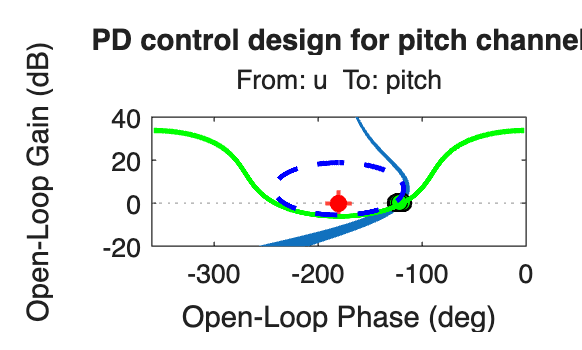

G_PD_pitch.InputName = {'e(2)'};
G_PD_pitch.OutputName = {'u(2)'};


L_PD_pitch = connect(G_PD_pitch, P(2,2), {'e(2)'}, {'bar_theta(2)'});
L_PD_pitch.InputName = 'u';
L_PD_pitch.OutputName = 'pitch';


figure(1),clf,hold on

M = [Ma Mb];
for k = 1:length(M)
    phi = linspace(0,2*pi,1e4);
    c = -1;
    r = 1/M(k);
    H = c + r*exp(1i*phi);

    mag_H = 20*log10( abs(H) );
    phi_H = angle( H )*180/pi;
    for i=1:length(phi_H)
        if( phi_H(i) > 0), phi_H(i) = phi_H(i)-360; end
    end

    if( k==1 )
        plot( phi_H(2:end-1),-mag_H(2:end-1),'--b',LineWidth=2 )
    else
        plot( phi_H(2:end-1),-mag_H(2:end-1),'-g',LineWidth=2 )
    end
end
for i = 1:20
    sys_i = usample(L_PD_pitch);
    Lw = squeeze( freqresp(sys_i,wp) );
    ang_Lw = angle(Lw)*180/pi;
    if( ang_Lw > 0 )
        ang_Lw = ang_Lw-360;
    end
    plot(ang_Lw,20*log10(abs(Lw)),'o',MarkerFaceColor='g',MarkerEdgeColor='k')
end
nichols(L_PD_pitch,{0.01,500}),plot(-180,0,'ro',MarkerFaceColor='r')
xlim([-360,0]),ylim([-20 40])
title('PD control design for pitch channel')
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 12);
set(gcf,'Units','centimeters','Position',[3 3 figureWidth figureRatio*figureWidth])
set(gcf,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[figureWidth figureRatio*figureWidth])
hold off


G_PD_pitch_DT = c2d(G_PD_pitch,Ts_c)


G_PD_pitch_DT =
 
  From input "e(2)" to output "u(2)":
  0.6115 z - 0.61
  ---------------
    z - 0.7694
 
Sample time: 0.005 seconds
Discrete-time transfer function.



% bode(L_PD_pitch)
% opts = robOptions('Display', 'on', 'Sensitivity', 'on');
% [margin, wcu, info] = robstab(feedback(L_PD_pitch, 1), opts);


Yaw specs

Ts = 3; % s
OS = 15; % %

Yaw controller design

lead = 70; % deg
K = 0.0025;

zeta = -log(OS/100)/sqrt( pi^2+log(OS/100)^2 );
wn = 4/zeta/Ts;
wp = wn*sqrt(1-2*zeta^2);

Ma = 1/( 2*zeta*sqrt(1-zeta^2) ); %overbound
Mb = .98; %underbound

w_max = wp;
phi_max = lead*pi/180;
alpha = w_max/tan( (phi_max+pi/2)/2 )

alpha = 0.3103

beta = w_max^2/alpha

beta = 9.9811


G_PD_yaw = (K*(1 + s/alpha))/(1 + s/beta)


G_PD_yaw =
 
  0.02495 s + 0.007743
  --------------------
    0.3103 s + 3.097
 
Continuous-time transfer function.


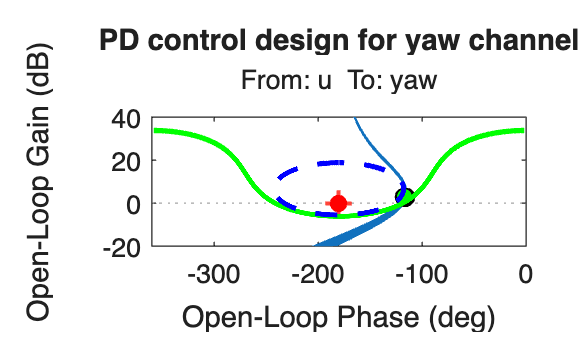

G_PD_yaw.InputName = {'e(3)'};
G_PD_yaw.OutputName = {'u(3)'};

% bodemag(G_PD_yaw)

L_PD_yaw = connect(G_PD_yaw, P(3,3), {'e(3)'}, {'bar_theta(3)'});
L_PD_yaw.InputName = 'u';
L_PD_yaw.OutputName = 'yaw';


% bodemag(L_PD_yaw)

figure(1),clf,hold on

M = [Ma Mb];
for k = 1:length(M)
    phi = linspace(0,2*pi,1e4);
    c = -1;
    r = 1/M(k);
    H = c + r*exp(1i*phi);

    mag_H = 20*log10( abs(H) );
    phi_H = angle( H )*180/pi;
    for i=1:length(phi_H)
        if( phi_H(i) > 0), phi_H(i) = phi_H(i)-360; end
    end

    if( k==1 )
        plot( phi_H(2:end-1),-mag_H(2:end-1),'--b',LineWidth=2 )
    else
        plot( phi_H(2:end-1),-mag_H(2:end-1),'-g',LineWidth=2 )
    end
end
for i = 1:20
    sys_i = usample(L_PD_yaw);
    Lw = squeeze( freqresp(sys_i,wp) );
    ang_Lw = angle(Lw)*180/pi;
    if( ang_Lw > 0 )
        ang_Lw = ang_Lw-360;
    end
    plot(ang_Lw,20*log10(abs(Lw)),'o',MarkerFaceColor='g',MarkerEdgeColor='k')
end
nichols(L_PD_yaw,{0.01,500}),plot(-180,0,'ro',MarkerFaceColor='r')
xlim([-360,0]),ylim([-20 40])
title('PD control design for yaw channel')
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 12);
set(gcf,'Units','centimeters','Position',[3 3 figureWidth figureRatio*figureWidth])
set(gcf,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[figureWidth figureRatio*figureWidth])
hold off


G_PD_yaw_DT = c2d(G_PD_yaw,Ts_c)


G_PD_yaw_DT =
 
  From input "e(3)" to output "u(3)":
  0.08041 z - 0.08029
  -------------------
      z - 0.9513
 
Sample time: 0.005 seconds
Discrete-time transfer function.



% bode(L_PD_yaw)
% opts = robOptions('Display', 'on', 'Sensitivity', 'on');
% [margin, wcu, info] = robstab(feedback(L_PD_yaw, 1), opts);


Simulate controller

AttController = "PDESO";
initVars;
if Simulate
    outPDESO = sim("Simulation/QuadSimControl.slx");
    figure, clf, hold on
    plot(outPDESO.att.time, outPDESO.att.signals.values(:,1))
    plot(outPDESO.att.time, outPDESO.att.signals.values(:,2))
    plot(outPDESO.att.time, outPDESO.att.signals.values(:,3))
    legend('yaw','pitch','roll')
    hold off
    figure, clf, hold on
    plot(outPDESO.pos.time, outPDESO.pos.signals.values(:,1))
    plot(outPDESO.pos.time, outPDESO.pos.signals.values(:,2))
    plot(outPDESO.pos.time, outPDESO.pos.signals.values(:,3))
    legend('x','y','z')
    hold off
end


## ADRC control design

Simulate = false;

w_c_ADRC = 1.8; % rad/s
w_o_ADRC = 7; % rad/s
b_0_roll_ADRC = 1/J_xx_u.NominalValue;
b_0_pitch_ADRC = 1/J_yy_u.NominalValue;
b_0_yaw_ADRC = 1/J_zz_u.NominalValue;

ONE = ones(1,1,'like',b_0_roll_ADRC);

A_eso_CT =  [0 0 0 1 0 0 0 0 0;
             0 0 0 0 1 0 0 0 0;
             0 0 0 0 0 1 0 0 0;
             0 0 0 0 0 0 1 0 0;
             0 0 0 0 0 0 0 1 0;
             0 0 0 0 0 0 0 0 1;
             0 0 0 0 0 0 0 0 0;
             0 0 0 0 0 0 0 0 0;
             0 0 0 0 0 0 0 0 0]*ONE;
B_eso_CT =  [0 0 0;
             0 0 0;
             0 0 0;
             b_0_roll_ADRC 0 0;
             0 b_0_pitch_ADRC 0;
             0 0 b_0_yaw_ADRC;
             0 0 0;
             0 0 0;
             0 0 0;]*ONE;

C_eso_CT =  [1 0 0 0 0 0 0 0 0;
             0 1 0 0 0 0 0 0 0;
             0 0 1 0 0 0 0 0 0]*ONE;

L_CT =   [3*w_o_ADRC   0           0;
            0       3*w_o_ADRC^2     0;
            0       0           w_o_ADRC^3;
            3*w_o_ADRC   0           0;
            0       3*w_o_ADRC^2     0;
            0       0           w_o_ADRC^3;
            3*w_o_ADRC   0           0;
            0       3*w_o_ADRC^2     0;
            0       0           w_o_ADRC^3;]*ONE;

ESO_CT = ss(A_eso_CT,B_eso_CT,C_eso_CT, zeros(3,3));

ADRC_ESO_DT = c2d(ESO_CT, Ts_c);

vec_wo = 1:0.01:1+0.01*(6+3-1);
obs_poles = -w_o_ADRC*vec_wo;
obs_poles = exp(obs_poles*Ts_c);

L_ADRC_DT = place(ADRC_ESO_DT.A',ADRC_ESO_DT.A'*ADRC_ESO_DT.C',obs_poles)';

Simulate controller

AttController = "ADRC";
initVars;
if Simulate
    outADRC = sim("Simulation/QuadSimControl.slx");
    figure, clf, hold on
    plot(outADRC.att.time, outADRC.att.signals.values(:,1))
    plot(outADRC.att.time, outADRC.att.signals.values(:,2))
    plot(outADRC.att.time, outADRC.att.signals.values(:,3))
    legend('yaw','pitch','roll')
    hold off
    figure, clf, hold on
    plot(outADRC.pos.time, outADRC.pos.signals.values(:,1))
    plot(outADRC.pos.time, outADRC.pos.signals.values(:,2))
    plot(outADRC.pos.time, outADRC.pos.signals.values(:,3))
    legend('x','y','z')
    hold off
end

% 
% tf(L_PID_roll.NominalValue(1,1,1,1))
% tf(G_PID_roll*Q(1,1)*F_i.NominalValue*exp(-F_td.NominalValue*s))
% tf(L_PID_pitch.NominalValue(1,1,1,1))
% tf(L_PID_yaw.NominalValue(1,1,1,1))
% 
% tf(L_PD_roll)
% tf(L_PD_pitch.NominalValue(1,1,1,1))
% tf(L_PD_yaw.NominalValue(1,1,1,1))

save('AttitudeControllers.mat', 'Ts_c', ...
        'G_PID_roll_DT', 'G_PID_pitch_DT', 'G_PID_yaw_DT', ...
        'b_0_roll_PDESO', 'b_0_pitch_PDESO', 'b_0_yaw_PDESO','PDESO_ESO_DT','L_PDESO_DT','G_PD_roll_DT', 'G_PD_pitch_DT', 'G_PD_yaw_DT',  ...
        'b_0_roll_ADRC', 'b_0_pitch_ADRC', 'b_0_yaw_ADRC','ADRC_ESO_DT','L_ADRC_DT','w_c_ADRC');
% save('AttitudeOpenLoop.mat', 'L_PID_roll', 'L_PID_pitch', 'L_PID_yaw', 'L_PD_roll', 'L_PD_pitch', 'L_PD_yaw')

% figure, clf, hold on
% subplot(3,1,1), hold on, ylabel('Yaw')
% plot(outPID.att.time, outPID.att.signals.values(:,1))
% plot(outPDESO.att.time, outPDESO.att.signals.values(:,1))
% plot(outADRC.att.time, outADRC.att.signals.values(:,1))
% subplot(3,1,2), hold on, ylabel('Pitch')
% plot(outPID.att.time, outPID.att.signals.values(:,2))
% plot(outPDESO.att.time, outPDESO.att.signals.values(:,2))
% plot(outADRC.att.time, outADRC.att.signals.values(:,2))
% subplot(3,1,3), hold on, ylabel('Roll')
% plot(outPID.att.time, outPID.att.signals.values(:,3))
% plot(outPDESO.att.time, outPDESO.att.signals.values(:,3))
% plot(outADRC.att.time, outADRC.att.signals.values(:,3))
% legend('PID','PD+ESO','ADRC', 'Location','best')
% hold off
% 
% figure, clf, hold on
% plot(outPID.motors.time, outPID.motors.signals.values(:,1))
% plot(outPDESO.motors.time, outPDESO.motors.signals.values(:,1))
% plot(outADRC.motors.time, outADRC.motors.signals.values(:,1))
% ylim([0.4 0.5])
% legend('PID','PD+ESO','ADRC', 'Location','best')
% hold off
